## EigenShoe runner

Links all the functions together

### Load images

% LoadImagesAndScale;
% names = ["BlackDiamond", "kronos", "LaSportiva"];
% Original test set, not needed anymore

[IMAGE_DIM, IMAGE_SIZE, num_shoes, LeftShoes, RightShoes, Lookup] = LoadImagesBig( 4 );

Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Ansazi\PXL_20230322_044837612.jpg for left shoe 9 of 24 
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Ansazi\PXL_20230322_044840953.jpg for left shoe 10 of 24 
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Ansazi\PXL_20230322_044843223.jpg for left shoe 11 of 24 
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Ansazi\PXL_20230322_044845565.jpg for left shoe 12 of 24 
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Instincts\PXL_20230322_044854468.jpg for left shoe 13 of 24 
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Instincts\PXL_20230322_044857318.jpg for left shoe 14 of 24 
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Instincts\PXL_20230322_044859618.jpg for left shoe 15 of 24 
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Instincts\PXL_20230322_044903888.jpg for left shoe 16 of 24 
Now reading C:\Users\


Shoes = LeftShoes

Shoes =      0     0     0     0     0     0     0     0   246   244   241   238   245   239   231   222   249   249   248   248   242   241   243   243
     0     0     0     0     0     0     0     0   245   243   241   238   245   239   232   223   249   249   249   248   241   242   243   244
     0     0     0     0     0     0     0     0   244   242   242   239   245   239   231   222   248   248   248   248   242   241   242   243
     0     0     0     0     0     0     0     0   246   243   241   239   245   239   231   222   249   249   249   249   242   241   242   243
     0     0     0     0     0     0     0     0   244   242   240   237   244   238   231   221   249   247   247   246   242   241   242   243
     0     0     0     0     0     0     0     0   244   241   239   237   244   238   231   221   247   247   246   247   242   240   241   241
     0     0     0     0     0     0     0     0   245   243   241   238   245   239   232   222   248   248   249   248  

## Get SVD

Do it around mean subtracted, so we have negative and positive sigma values, centering all of our data.

avgShoe = mean(Shoes,2);

Shoes = Shoes-avgShoe*ones(1,size(Shoes,2));
[U,S,V] = svd(Shoes,'econ');



norm(Shoes - U * S * V');
disp("How close the svd is to the matrix: " + num2str(ans));

How close the svd is to the matrix: 1.3063e-10


### Plot our SVD and average face

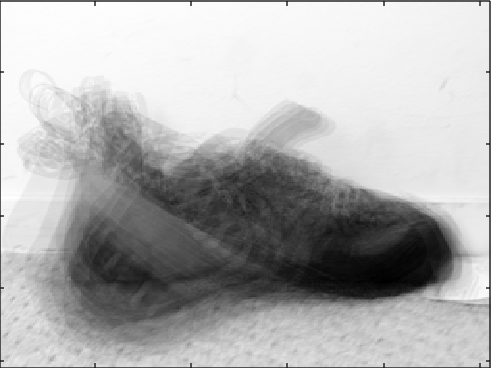

figure(1), axes('position',[0  0  1  1]), axis off
imagesc(reshape(avgShoe, IMAGE_DIM, IMAGE_DIM))
title("avg shoe"), colormap gray;

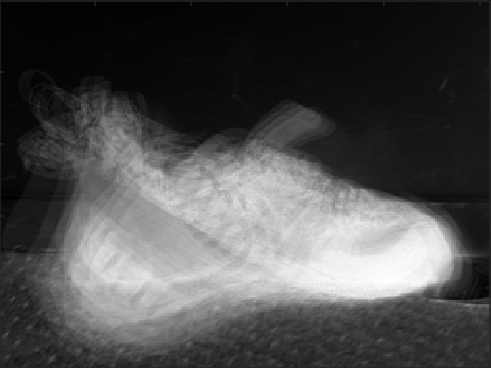


figure(2), axes('position',[0  0  1  1]), axis off
title("first eigenshoe"), colormap gray;
imagesc(reshape(U(:,1), IMAGE_DIM, IMAGE_DIM))

## Get r values

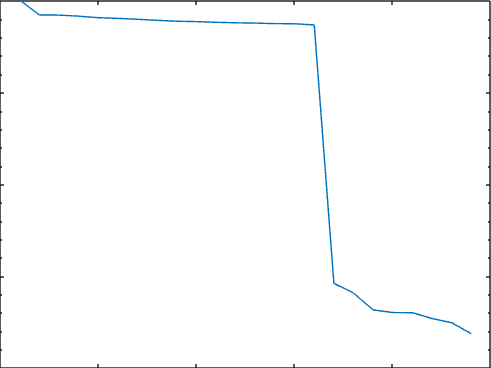

semilogy(diag(S)), grid off
xlabel('r')
ylabel('Singular value, \sigma_r')

## Plot all calculated eigenfaces

n = IMAGE_DIM;
m = IMAGE_DIM;
EigenShoes = zeros(n*3, m*2);
count = 1;
disp("EIGEN")

EIGEN


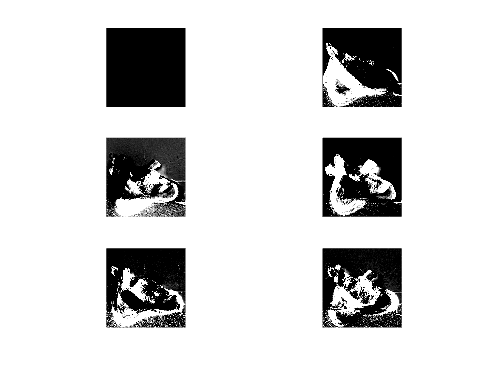

figure(2)
for i = 1:3
    for j = 1:2
        EigenShoes(1+(i-1)*n : i*n , 1+(j-1)*m : j*m) ...
            = reshape(U(:,count), n, m);
        subplot(3,2, count);
        imshow((reshape(U(:,count), n, m) + 0) * 500);

        count = count + 1;
    end
end

disp("EGFACE")

EGFACE


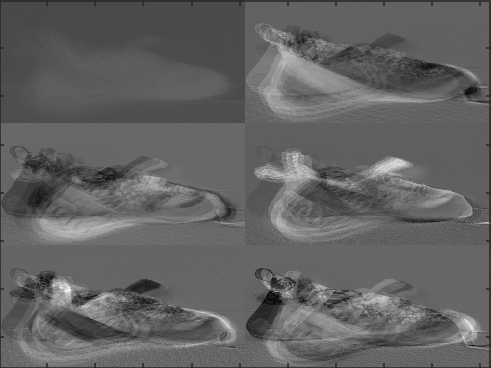

figure(1), axes('position',[0  0  1  1]), axis off
imagesc(EigenShoes), colormap gray;


% Some are positive and negative, I could try to put it in a sigmoid
% functoin and mult by 255 ??


## Now show eigenface reconstruction of image that was omitted from test set

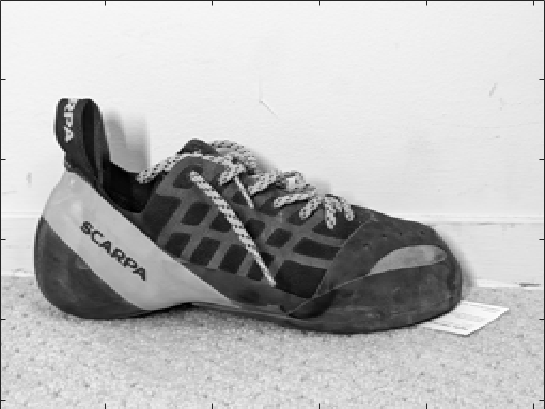

testFace = imread("TestLR/Instinct.jpg");
testFace = im2gray(testFace);
testFace = imresize(testFace, [IMAGE_DIM, IMAGE_DIM]);
imagesc(reshape(testFace,n,m)), colormap gray

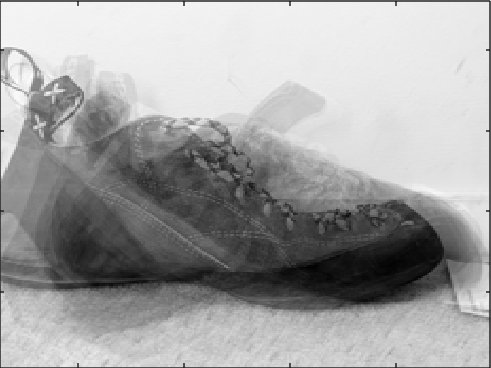

testFace = reshape(double( im2gray(testFace) ) , IMAGE_SIZE, 1);

testFaceMS = testFace - avgShoe;
count = 1;
for r=[6] 
    reconShoe = avgShoe + (U(:,1:r)*(U(:,1:r)'*testFaceMS));
    imagesc(reshape(reconShoe,n,m))
    figure(count), axes('position',[0  0  1  1]), axis off
    title(['r=',num2str(r, "%d")])
    count = count + 1;
end

## Project person 2 and 7 onto PC5 and PC6

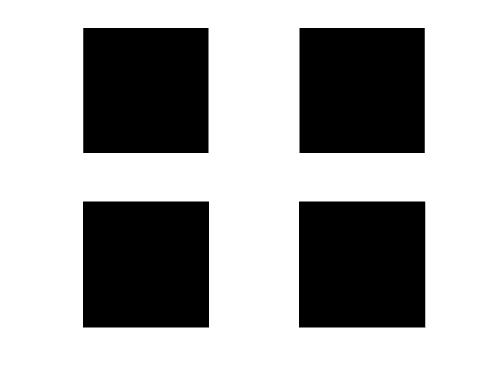

close
Shoe1 = Shoes(:, [1, 2]);
Shoe2 = Shoes(:, [3, 4]);

both = [ Shoe1 Shoe2];

figure

for i = 1 : size(both, 2)
    img = reshape( both(:, i) , IMAGE_DIM, IMAGE_DIM);
    subplot(2, 2, i)
    imshow(img);
end

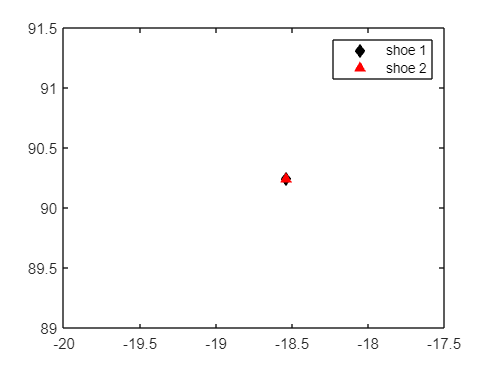



Shoe1 = Shoe1 - avgShoe*ones(1,size(Shoe1,2));
Shoe2 = Shoe2 - avgShoe*ones(1,size(Shoe2,2));

PCAmodes = [3, 4, 5];    % Project onto PCA modes 5 and 6
PCACoordsP1 = U(:,PCAmodes)'*Shoe1;
PCACoordsP2 = U(:,PCAmodes)'*Shoe2;

figure

axis off
plot(PCACoordsP1(1,:),PCACoordsP1(2,:),'kd', 'MarkerFaceColor', 'k')
hold on
plot(PCACoordsP2(1,:),PCACoordsP2(2,:),'r^', 'MarkerFaceColor', 'r')
legend('shoe 1', 'shoe 2')